
D = linspace(0, 0.5, 50);   % D从0到0.5，取100个点
varphi = linspace(0, 1, 101);  % varphi从0到1，取100个点

% 创建网格
[D_grid, varphi_grid] = meshgrid(D, varphi);

% 初始化P矩阵
P = zeros(size(D_grid));

% 遍历D和varphi的网格，计算P
for i = 1:length(D)
    for j = 1:length(varphi)
        d = D(i);
        phi = varphi(j);
        
        % 第一个情况
        if phi >= 0 && phi < 0.5 - d
            P(j, i) = - 2*d^2 - 4*d*phi + d;
        
        % 第二个情况
        elseif phi >= 0.5 - d && phi < 0.5
            P(j, i) = 2*d^2 + 4*d*phi - 3*d + (2*phi - 1)^2;
        
        % 第三个情况
        elseif phi >= 0.5 && phi < 1 - d
            P(j, i) = 2*d^2 + 4*d*phi - 3*d;
        
        % 第四个情况
        elseif phi >= 1 - d && phi <= 1
            P(j, i) = - 2*d^2 - 4*d*phi + 5*d - 4*(phi - 1)^2;
        end
    end
end

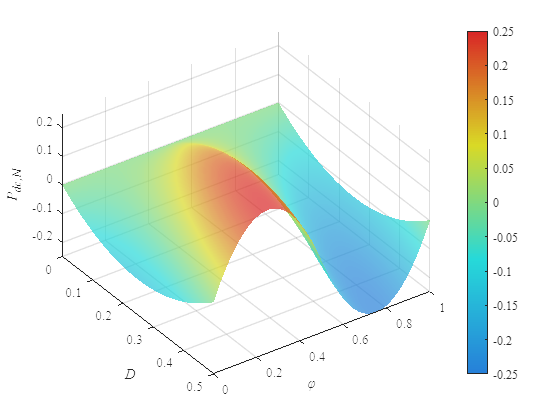


% 绘制3D图
figure;
surf(D_grid, varphi_grid, -P,'FaceAlpha', 0.7);

% 禁用边框线
set(gca, 'FontName', 'Times New Roman');
%set(gca, 'EdgeColor', 'none'); % 这行可以去掉曲面连接线

% 设置颜色映射
n = 256; % 定义颜色分辨率
cmap = [linspace(0, 0, n/4)', linspace(0.5, 1, n/4)', linspace(1, 1, n/4)'; ... % 蓝到绿
        linspace(0, 1, n/4)', linspace(1, 1, n/4)', linspace(1, 0, n/4)'; ... % 绿到黄
        linspace(1, 1, n/4)', linspace(1, 0, n/4)', linspace(0, 0, n/4)'];    % 黄到红
gray_level = 0.5; % 接近灰色的值（0.5是中性灰）
desaturated_cmap = cmap * 0.7 + gray_level * (1 - 0.7); % 线性插值降低饱和度
colormap(desaturated_cmap);
colorbar;

% 平滑显示
shading interp;  % 平滑插值

% 设置视角和网格
view(55, 45); % 设置视角
grid on;
hold on;
% 添加标题和标签
xlabel('\it{D}');
ylabel('\it{φ}');
zlabel('\it{P}_{dc,N}');

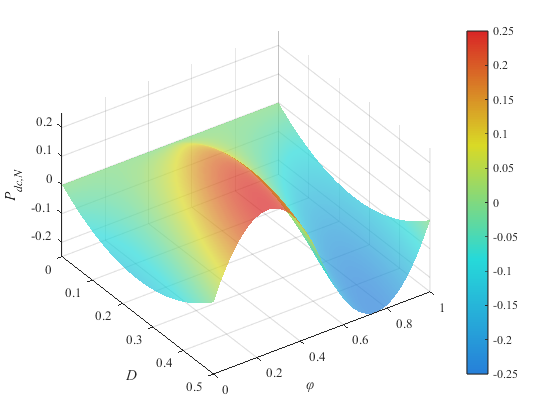

% 导出为 PDF 格式，设置输出尺寸
exportgraphics(gcf, 'Output power versus D and varphi1226.pdf', 'ContentType', 'image', 'BackgroundColor', 'none');

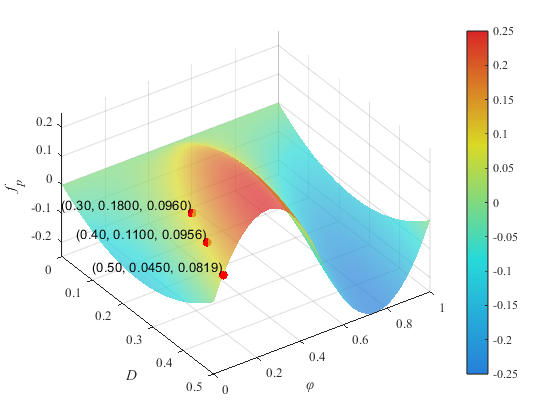

% % 要标注的点
% points = [0.5, 0.045; 0.4, 0.11; 0.3, 0.18];  % 点的坐标
% % 计算这些点对应的P值
% for i = 1:size(points, 1)
%     d = points(i, 1); % 获取D的值
%     phi = points(i, 2); % 获取phi的值
%     
%     % 计算P值
%     if phi >= 0 && phi < 0.5 - d
%         P_value = - 2*d^2 - 4*d*phi + d;
%     elseif phi >= 0.5 - d && phi < 0.5
%         P_value = 2*d^2 + 4*d*phi - 3*d + (2*phi - 1)^2;
%     elseif phi >= 0.5 && phi < 1 - d
%         P_value = 2*d^2 + 4*d*phi - 3*d;
%     else
%         P_value = - 2*d^2 - 4*d*phi + 5*d - 4*(phi - 1)^2;
%     end
%     
%     % 在图上标注点
%     hold on; % 保持当前图形
%     plot3(d, phi, -P_value, 'ro', 'MarkerFaceColor', 'r'); % 在该点上画红色圆点
%     text(d, phi, -P_value, sprintf(' (%.2f, %.4f, %.4f)', d, phi, -P_value), ...
%         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10);
% end